## **Visualisation des différentes configurations du robot **

Ce code permet, après definition des variables, des longueurs des bras du robot, de la position desiree de l'effecteur, du nombre de solution souhaités affichées, et des butées de chaque articulation, de générer l'espace de travail du robot, puis de le visualiser dans les configurations possibles pour atteindre le point désiré par résolution de la cinmeatique inverse par la méthode variationnelle. 

### **Definition des variables**

% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du quatrieme bras
a5 = 2; % Longueur du cinquieme bras

% Définir la position désirée de l'effecteur
x_desired = 5.8

x_desired = 5.8000

y_desired = 6

y_desired = 6


% Nombre de solutions souhaitées
num_configurations = 12; 


theta1_min = -90

theta1_min = -90

theta1_max = 90

theta1_max = 90

theta2_min = -95

theta2_min = -95

theta2_max = 95

theta2_max = 95

theta3_min = -90

theta3_min = -90

theta3_max = 90

theta3_max = 90

theta4_min = -90

theta4_min = -90

theta4_max = 90

theta4_max = 90

theta5_min = -90

theta5_min = -90

theta5_max = 90

theta5_max = 90


% Stocker les valeurs dans la matrice butee
butee = [theta1_min, theta1_max; theta2_min, theta2_max; theta3_min, theta3_max; theta4_min, theta4_max; theta5_min, theta5_max];
% Enregistrement de la matrice dans un fichier .mat
save('butee.mat', 'butee');
% Convertir les limites des intervalles de degrés en radians
butee_rad = deg2rad(butee)

butee_rad =    -1.5708    1.5708
   -1.6581    1.6581
   -1.5708    1.5708
   -1.5708    1.5708
   -1.5708    1.5708


### Rayon d'action des articulations


% Ouvrir une nouvelle figure pour les arcs d'action
figure;
hold on; % Permet de superposer tous les arcs sur le même graphique

% Longueurs des segments
longueurs = [a1, a2, a3, a4, a5];

% Définir les coordonnées des centres des segments
centres = zeros(6, 2);
centres(1, :) = [0, 0];               % Centre du segment OA
centres(2, :) = [a1,0];               % Centre du segment AB
centres(3, :) = [a1 + a2, 0];         % Centre du segment BC
centres(4, :) = [a1 + a2 + a3, 0];    % Centre du segment CD
centres(5, :) = [a1 + a2 + a3 + a4, 0];% Centre du segment DE
centres(6, :) = [a1 + a2 + a3 + a4 + a5, 0];% Fin du segment DE

% Couleurs pour chaque segment
colors = ['b', 'r', 'g', 'y', 'm'];

% Boucle pour tracer les arcs de cercle pour chaque segment
for i = 1:size(centres, 1) - 1
    % Définir la plage d'angles pour le segment actuel
    theta_range = linspace(butee_rad(i, 1), butee_rad(i, 2), 100);
    
    % Calculer les points de l'arc pour le segment actuel
    x_arc = centres(i, 1) + longueurs(i) * cos(theta_range);
    y_arc = centres(i, 2) + longueurs(i) * sin(theta_range);
    
    % Préparer les points pour le remplissage
    x_fill = [centres(i, 1), x_arc, centres(i, 1)];
    y_fill = [centres(i, 2), y_arc, centres(i, 2)];
    
    % Remplir l'arc de cercle avec la couleur spécifiée
    fill(x_fill, y_fill, colors(i), 'FaceAlpha', .2, 'DisplayName', sprintf('Rayon d''action %d de l''articulation', i));
    
    % Dessiner l'arc de cercle avec la même couleur que le remplissage
    plot(x_arc, y_arc, 'Color', colors(i), 'LineWidth', 1.5, 'DisplayName', sprintf('Rayon action %d de l''articulation', i), 'HandleVisibility', 'off');
    
    % Dessiner la ligne reliant l'extrémité de l'arc au centre avec la même couleur que l'arc
    plot([centres(i, 1), x_arc(1)], [centres(i, 2), y_arc(1)], 'Color', colors(i), 'LineWidth', 1.5, 'HandleVisibility', 'off');
    
    % Dessiner la ligne reliant le début de l'arc au centre avec la même couleur que l'arc
    plot([centres(i, 1), x_arc(end)], [centres(i, 2), y_arc(end)], 'Color', colors(i), 'LineWidth', 1.5, 'HandleVisibility', 'off');
end


% Dessiner le robot dans sa position initiale avec des angles d'articulation nuls
robot_x = [0, a1, a1 + a2, a1 + a2 + a3, a1 + a2 + a3 + a4, a1 + a2 + a3 + a4 + a5];
robot_y = [0, 0, 0, 0, 0, 0];
plot(robot_x, robot_y, 'k-o', 'LineWidth', 2, 'MarkerSize', 2, 'DisplayName', 'Robot');


% Ajouter des rectangles autour des segments
rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
drawSegmentRectangle([0, 0], [a1, 0], rectWidth, 'b');
drawSegmentRectangle([a1, 0], [a1 + a2, 0], rectWidth, 'r');
drawSegmentRectangle([a1 + a2, 0], [a1 + a2 + a3, 0], rectWidth, 'g');
drawSegmentRectangle([a1 + a2 + a3, 0], [a1 + a2 + a3 + a4, 0], rectWidth, 'y');
drawSegmentRectangle([a1 + a2 + a3 + a4, 0], [a1 + a2 + a3 + a4 + a5, 0], rectWidth, 'm');
% Nombre de points à générer
num_points = 3000;


### Affichage de l'espace de travail : 

- liste pour **stocker les coordonnees atteignables,**

- definition de l**'echantillon d'angles testés et du pas**

% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];

% % Définir la grille d'angles d'articulation
theta1_range = linspace(butee_rad(1, 1), butee_rad(1, 2), 8);
theta2_range = linspace(butee_rad(2, 1), butee_rad(2, 2), 8);
theta3_range = linspace(butee_rad(3, 1), butee_rad(3, 2), 8);
theta4_range = linspace(butee_rad(4, 1), butee_rad(4, 2), 8);
theta5_range = linspace(butee_rad(5, 1), butee_rad(5, 2), 8);
% % Nombre de pas pour chaque articulation
% step_angle = 15; % Espacement entre chaque angle en degrés

- **calcul des coordonnees atteignables** pour chaque combinaison d'angles possibles de l'echantillon, par **cinematique directe**

% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            for l = 1:length(theta4_range)
                for m = 1:length(theta5_range)
                    % Calculer les coordonnées de l'effecteur
                    x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                     % Ajouter les coordonnées à la liste
                    reachable_points = [reachable_points; x, y];
                end
            end
        end
    end
end
% % Générer les coordonnées atteignables pour chaque combinaison d'angles possibles
% for theta1 = theta1_min:step_angle:theta1_max
%     for theta2 = theta2_min:step_angle:theta2_max
%         for theta3 = theta3_min:step_angle:theta3_max
%             for theta4 = theta4_min:step_angle:theta4_max
%                 for theta5 = theta5_min:step_angle:theta5_max
%                     % Calculer les coordonnées de l'effecteur
%                     x = a1 * cosd(theta1) + a2 * cosd(theta1 + theta2) + a3 * cosd(theta1 + theta2 + theta3) + a4 * cosd(theta1 + theta2 + theta3 + theta4) + a5 * cosd(theta1 + theta2 + theta3 + theta4 + theta5);
%                     y = a1 * sind(theta1) + a2 * sind(theta1 + theta2) + a3 * sind(theta1 + theta2 + theta3) + a4 * sind(theta1 + theta2 + theta3 + theta4) + a5 * sind(theta1 + theta2 + theta3 + theta4 + theta5);
%                     % Ajouter les coordonnées à la liste
%                     reachable_points = [reachable_points; x, y];
%                 end
%             end
%         end
%     end
% end
% % Convertir les coordonnées en une matrice de points
points_atteign = [reachable_points(:, 1), reachable_points(:, 2)];


- affichage des **contours de l'espace de travail**

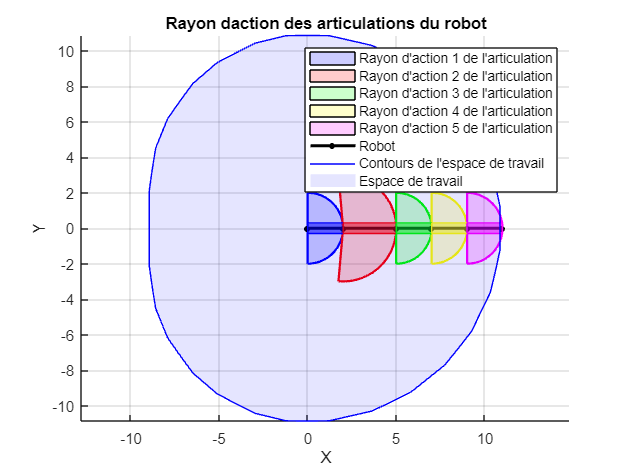

% % Calculer les contours convexes du nuage de points avec une méthode plus précise
K = convhull(points_atteign);
% % Tracer les contours de l'espace de travail
plot(points_atteign(K, 1), points_atteign(K, 2), 'b', 'LineWidth', .5, 'DisplayName', 'Contours de l''espace de travail');
fill(points_atteign(K, 1), points_atteign(K, 2), 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Espace de travail');

% Mettre à jour le graphique
title('Rayon daction des articulations du robot' );
xlabel('X');
ylabel('Y');
axis equal; % Assure que les proportions X/Y sont égales
grid on;
legend show;

### Resolution IK après vérification de l'appartenance du point cible à l'espace de travail (revoir la verif)

Cette partie procède tout d'abord à une verification de l'appartenance du point désiré de l'effecteur à l'esapce de travail du robot. Si cela est vérifé on lance alors le calcul de cinématique inverse par la méthode variationnelle. 

Puis on affiche les solutions , d'abord en raidan et ensuite en degrès.

% Vérifier si le point cible est à l'intérieur des contours convexes
dans_l_espace_de_travail = inpolygon(x_desired, y_desired, points_atteign(K, 1), points_atteign(K, 2));

% Afficher le résultat
if dans_l_espace_de_travail
    disp('Le point cible est à l''intérieur de l''espace de travail.');
    % Appeler la fonction pour trouver les angles d'articulation
    all_solutions = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations);
else
    disp('Le point cible est à l''extérieur de l''espace de travail.');
end

Le point cible est à l'intérieur de l'espace de travail.


Valeurs des angles, en radian, de chaque articulation du robot pour la position désirée :
    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé
    0.7808    0.2587    0.7206    5.1642    5.0266    5.8000    6.0000
    0.4995    0.2914    0.3805    4.6899    2.3329    5.8000    6.0000
    0.4090    0.0443    2.0782    4.4782    0.0604    5.8000    6.0000
    6.2456    0.6053    0.2129    1.5394    4.8823    5.8000    6.0000
    1.4000    6.0178    6.1480    4.4938    1.3414    5.8000    6.0000
    0.3202    6.1698    1.3009    5.2851    1.5316    5.8000    6.0000
    0.6889    5.9628    0.5593    5.7717    2.0576    5.8000    6.0000
    0.0795    1.0336    0.7810    4.1975    1.1481    5.8000    6.0000
    1.2978    0.0314    4.2015    1.5202    6.1216    5.8000    6.0000
    0.8624    6.0844    1.7479    4.4891    5.7366    5.8000    6.0000
    0.5088    6.1378    0.9367    5.2138    2.0041    5.8000    6.0000
    0.6904    0.3935    0.5281    5.4430    4.7916    5.


% Enregistrer les solutions dans un fichier
save('solutions.mat', 'all_solutions');

## Affichage du robot dans les positions solutions résolues par la cinématique inverse

### Affichage de l'espace de travail : 

- tracer **le point cible que l'on veut atteindre**

% Initialiser une figure
figure;
hold on;
%Tracer le point désiré en rouge
plot(x_desired, y_desired, 'ro', 'MarkerSize', 10, 'DisplayName', 'Point désiré');

- tracer le** nuage des points atteignables**

%Tracer le nuage de points représentant l'espace de travail atteignable
scatter(reachable_points(:, 1), reachable_points(:, 2), 1, 'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);

- affichage des **contours de l'espace de travail**

% % Convertir les coordonnées en une matrice de points
points_atteign = [reachable_points(:, 1), reachable_points(:, 2)];
% % Calculer les contours convexes du nuage de points avec une méthode plus précise
K = convhull(points_atteign);
% % Tracer les contours de l'espace de travail
plot(points_atteign(K, 1), points_atteign(K, 2), 'b', 'LineWidth', .5, 'DisplayName', 'Contours de l''espace de travail');
fill(points_atteign(K, 1), points_atteign(K, 2), 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Espace de travail');

### Affichage du robot

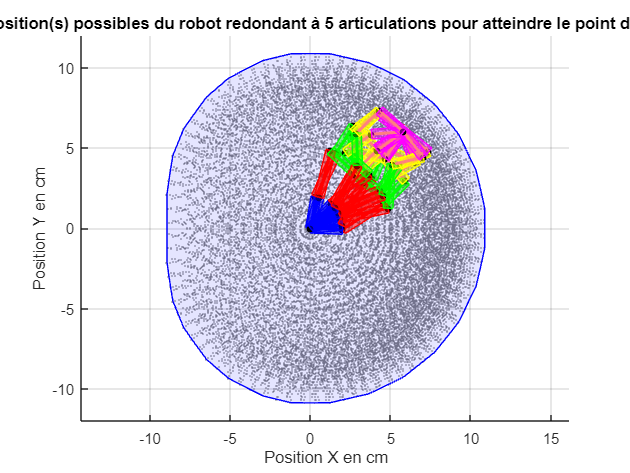

Le point cible est à l'intérieur de l'espace de travail.


% Vérifier si le point cible est à l'intérieur des contours convexes
dans_l_espace_de_travail = inpolygon(x_desired, y_desired, points_atteign(K, 1), points_atteign(K, 2));

% Afficher le résultat
if dans_l_espace_de_travail
    disp('Le point cible est à l''intérieur de l''espace de travail.');
    % Appeler la fonction pour trouver les angles d'articulation
    %disp('Limites de lespace de travail');
    min_x = min(reachable_points(:, 1));
    max_x = max(reachable_points(:, 1));
    min_y = min(reachable_points(:, 2));
    max_y = max(reachable_points(:, 2));% Définir les couleurs pour chaque type de segment
    color_segment_OA = 'b'; % Segment OA
    color_segment_AB = 'r'; % Segment AB
    color_segment_BC = 'g'; % Segment BC
    color_segment_CD = 'm'; % Segment CD
    color_segment_DE = 'y'; % Segment DE
    
    % Visualisation des configurations du robot
    for i = 1:size(all_solutions, 1)
        % Extraire les angles d'articulation pour cette configuration
        theta1 = all_solutions(i, 1);
        theta2 = all_solutions(i, 2);
        theta3 = all_solutions(i, 3);
        theta4 = all_solutions(i, 4);
        theta5 = all_solutions(i, 5);
    
        % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
        O = [0, 0]; % Position de l'origine
        A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
        B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
        C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
        D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
        E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)
    
        % Tracer le robot pour cette configuration 
        plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'DisplayName', ['Segment OA - Solution ', num2str(i)]); % Segment OA
        plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'DisplayName', ['Segment AB - Solution ', num2str(i)]); % Segment AB
        plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'DisplayName', ['Segment BC - Solution ', num2str(i)]); % Segment BC
        plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'DisplayName', ['Segment CD - Solution ', num2str(i)]); % Segment BC
        plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'DisplayName', ['Segment DE - Solution ', num2str(i)]); % Segment BC
        scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    
        % Ajouter des rectangles autour des segments
        rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
        drawSegmentRectangle(O, A, rectWidth, 'b');
        drawSegmentRectangle(A, B, rectWidth, 'r');
        drawSegmentRectangle(B, C, rectWidth, 'g');
        drawSegmentRectangle(C, D, rectWidth, 'y');
        drawSegmentRectangle(D, E, rectWidth, 'm');  
    end 
    
    % Calculer les limites des axes
    xlim([-12, 12]); 
    ylim([-12, 12]);
    axis equal
    
    % Configurer le titre et les étiquettes des axes
    title('Position(s) possibles du robot redondant à 5 articulations pour atteindre le point désiré');
    xlabel('Position X en cm');
    ylabel('Position Y en cm');
    
    % Affichage de la grille
    grid on;
    hold off; 
    else
    disp('Le point cible est à l''extérieur de l''espace de travail.');
end

### Fonctions

% Fonction cinematique inverse et pour créer un rectangle autour d'un segment

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
end

function [all_solutions] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations)
    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.0000001;
    max_iterations = 100;
    
        % Initialiser une liste pour stocker les configurations atteignables
    all_solutions = [];

    % Recherche des configurations
    while size(all_solutions, 1) < num_configurations
        % Initialiser les angles d'articulation en fonction des butées
        % Générer des angles d'articulation aléatoires entre 0 et 2*pi radians
        theta1 = rand * 2*pi;
        theta2 = rand * 2*pi;
        theta3 = rand * 2*pi;
        theta4 = rand * 2*pi;
        theta5 = rand * 2*pi;

        % Boucle d'itération pour trouver les angles d'articulation
        for i = 1:max_iterations
            % Calculer les équations directes de cinématique directe
            x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
            y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
            % Calculer l'erreur de position
            error_x = x_desired - x;
            error_y = y_desired - y;
            error = [error_x; error_y];

            % Calculer les dérivées partielles
            dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
            dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
            dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            % Construire la Jacobienne
            J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
             dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
            % Vérifier la convergence
            if norm(error) < tolerance
                %disp('Convergence atteinte.');
                % Stocker la solution
                all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x, y]];
                
                break;
            end

            % Calculer la variation des angles d'articulation
            delta_theta = pinv(J) * error;
    
            % Mise a jour des les angles d'articulation
            theta1 = theta1 + delta_theta(1);
            theta2 = theta2 + delta_theta(2);
            theta3 = theta3 + delta_theta(3);
            theta4 = theta4 + delta_theta(4);
            theta5 = theta5 + delta_theta(5);

            % Maintien des angles entre 0 et 2*pi
            theta1 = mod(theta1, 2*pi);
            theta2 = mod(theta2, 2*pi);
            theta3 = mod(theta3, 2*pi);
            theta4 = mod(theta4, 2*pi);
            theta5 = mod(theta5, 2*pi);
            
        end
        
    end
     % Afficher toutes les configurations trouvées en radian
    disp('Valeurs des angles, en radian, de chaque articulation du robot pour la position désirée :');
    disp('    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé');
    disp(all_solutions);  
    
    % Convertion des angles de radians en degrés et afficher les résultats
    all_solutions_deg = rad2deg(all_solutions(:, 1:5));
    % Afficher toutes les configurations trouvées en degrrs
    disp('Valeurs des angles, en degrès, de chaque articulation  du robot pour la position désirée :');
    disp('    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé')
    disp([all_solutions_deg, all_solutions(:, 6:7)]);
end